clear; clc;

% Параметы
a = [10; 10; 10];
d = [1; 1; 1];
b = [10000; 1000];
t = [0.1 0.5 0];

% Целевая функция
Q = @(x) sum((a + d.*x(:)).*x(:));

% Метод Лагранжа
[x,Q_min] = lagrange(Q, a, d, b, t);

$$L = x_{1}\,\left(x_{1}+10\right)-\lambda_{1}\,\left(x_{1}+x_{2}+x_{3}-10000\right)+x_{2}\,\left(x_{2}+10\right)+x_{3}\,\left(x_{3}+10\right)-\lambda_{2}\,\left(\frac{x_{1}}{10}+\frac{x_{2}}{2}-1000\right)$$

$$grad = \left(\begin{array}{c} 2\,x_{1}-\frac{\lambda_{2}}{10}-\lambda_{1}+10=0\\ 2\,x_{2}-\frac{\lambda_{2}}{2}-\lambda_{1}+10=0\\ 2\,x_{3}-\lambda_{1}+10=0\\ 10000-x_{2}-x_{3}-x_{1}=0\\ 1000-\frac{x_{2}}{2}-\frac{x_{1}}{10}=0 \end{array}\right)$$

sol = struct with fields:
         x1: 85000/21
         x2: 25000/21
         x3: 100000/21
    lambda1: 200210/21
    lambda2: -100000/7


$$G = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 2 & 0\\ 0 & 0 & 2 \end{array}\right)$$

$$Fg = 2\,{\delta_{1}}^{2}+2\,{\delta_{2}}^{2}+2\,{\delta_{3}}^{2}$$

disp('*Результаты работы функции метода Лагранжа*');

*Резултаты работы функции метода Лагранжа*


lab6_print(x, Q_min);

Минимальная себестоимость выпуска (Q): | 40576190.48
----------------------------------------------------
Оптимальный объемы выпуска x1:         | 4047.62
Оптимальный объемы выпуска x2:         | 1190.48
Оптимальный объемы выпуска x3:         | 4761.90
----------------------------------------------------



% fmincon
options = optimoptions('fmincon', 'Display','off');
[x, Q_min] = fmincon(Q, [0;0;0], [], [], [1,1,1; t], b, [0;0;0], [], [], options);
disp('*Результаты работы функции fmincon*');

*Резултаты работы функции fmincon*


lab6_print(x, Q_min);

Минимальная себестоимость выпуска (Q): | 40576190.48
----------------------------------------------------
Оптимальный объемы выпуска x1:         | 4047.62
Оптимальный объемы выпуска x2:         | 1190.48
Оптимальный объемы выпуска x3:         | 4761.90
----------------------------------------------------


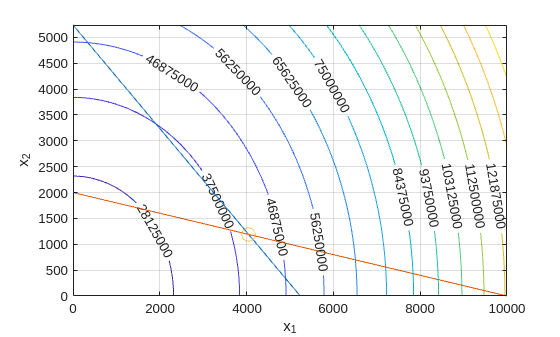


% График
lab6_plot(Q, b, t, x);


function [x_opt, Q_min] = lagrange(Q, a, d, b, t)
    % Символьные переменные
    x = sym('x', [3,1], 'real');
    lambda = sym('lambda', [2,1], 'real');
    delta = sym('delta', [3,1], 'real');

    % Функция Лагранжа
    L = Q(x) + lambda(1)*(b(1) - sum(x)) + lambda(2)*(b(2) - t*x)
    
    % Производные
    grad = gradient(L, [x; lambda]) == 0
    
    % Решение
    sol = solve(grad, [x; lambda]);
    
    % Матрица Гессе
    G = hessian(L, x)
    Fg = delta' * G * delta

    % Вывод результатов
    x_opt = double([sol.x1; sol.x2; sol.x3]);
    Q_min = Q(x_opt);
end

function [] = lab6_plot(Q, b, t, x)
    % Сетка
    [X1, X2] = meshgrid(linspace(0, b(2)/t(1), 100), ...
                        linspace(0, b(1)-x(3), 100));
    
    % Вычисляем Q через arrayfun (сохраняет x(:))
    Q_vals = arrayfun(@(x1,x2) Q([x1; x2; x(3)]), X1, X2);
    
    % График
    levels = [linspace(0, 1.5*10^8, 17)];
    contour(X1, X2, Q_vals, levels, 'ShowText','on');
    grid on; hold on;
    xlabel('x_1'); ylabel('x_2');
    
    % Ограничения
    plot([0, b(1)-x(3)],[b(1)-x(3), 0])
    plot([0, b(2)/t(1)],[b(2)/t(2), 0])

    % Оптимум
    plot(x(1), x(2),'Marker','o', 'MarkerSize',10)
end

function [] = lab6_print(x, Q_min)
    fprintf('Минимальная себестоимость выпуска (Q): | %.2f\n', Q_min);
    disp(   '----------------------------------------------------');
    fprintf('Оптимальный объемы выпуска x1:         | %.2f\n', x(1));
    fprintf('Оптимальный объемы выпуска x2:         | %.2f\n', x(2));
    fprintf('Оптимальный объемы выпуска x3:         | %.2f\n', x(3));
     disp(   '----------------------------------------------------');
end